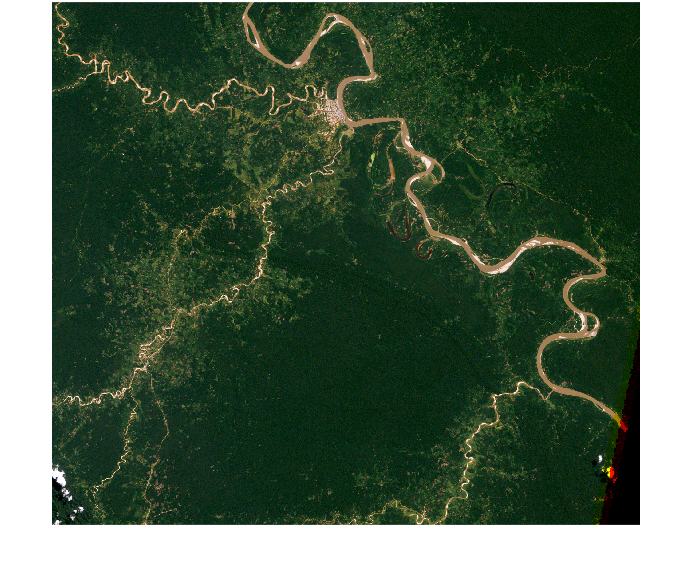

clear;
M = 1701; N = 1913;
image = zeros(2, M, N, 3);
image(1,:,:,:) = imread("imageSeries2_year2001.png");
image(2,:,:,:) = imread("imageSeries2_year2019.png");
image = uint8(image);
imshow(squeeze(image(1,:,:,:)))

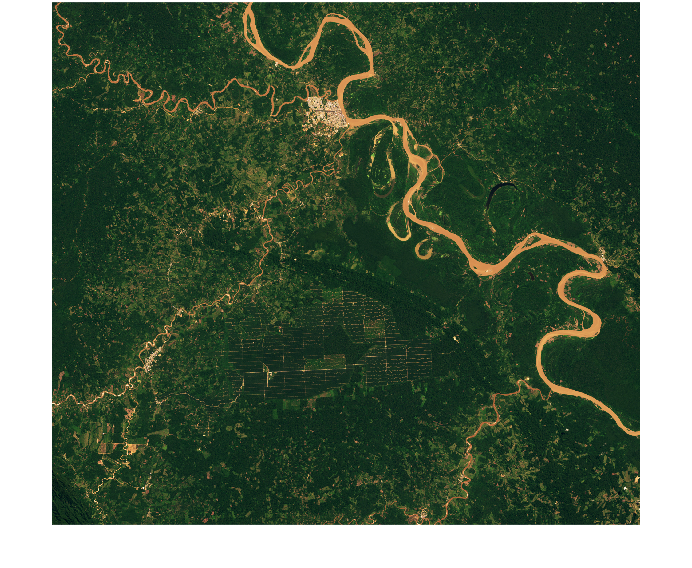

imshow(squeeze(image(2,:,:,:)))

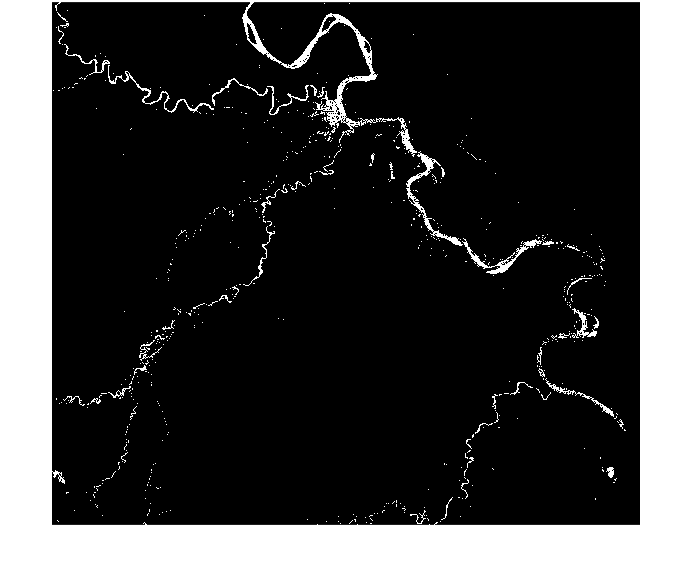


%thresholds specific to series of images
rThresh = [0  .45];
gThresh = [0 1];
bThresh = [.65 1];

BW = zeros(2, M, N); %instantiate BW image array
BW(1, :, :) = getMask(squeeze(image(1,:,:,:)), rThresh, gThresh, bThresh);
BW(2, :, :) = getMask(squeeze(image(2,:,:,:)), rThresh, gThresh, bThresh);

imshow(squeeze(BW(1,:,:)))

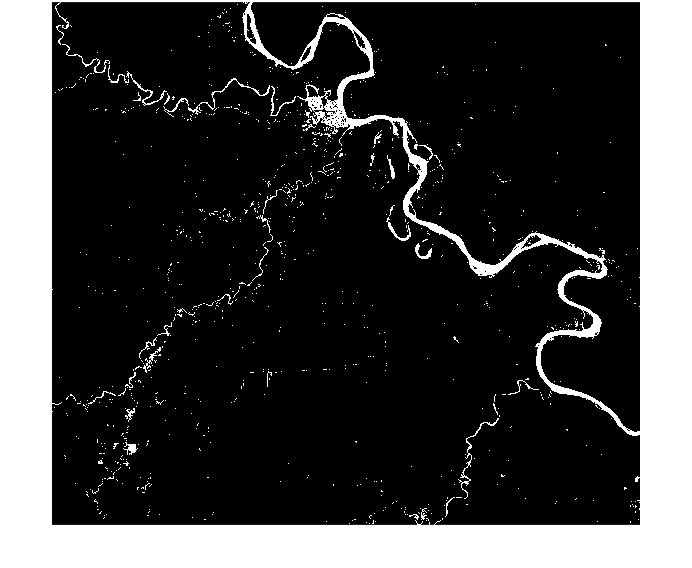

imshow(squeeze(BW(2, :,:)))


%indices to avoid (that are 1 in the BW)
idx = zeros(2, M, N)

idx = idx(:,:,1) =

  Columns 1 through 1,666

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

idx(1, :, :) = BW(1,:,:)~=1;
idx(2, :, :) = BW(2, :, :) ~= 1;
